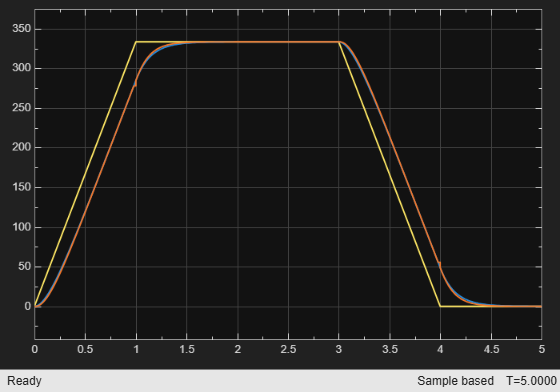

% =========================================================================
% Jednoduche Simulink schema: Spojity a Diskretni PID regulator vozidla
% =========================================================================
clear; clc; close all;

%% 1. Parametry modelu a PID (z identifikace)
K   = 7.596;      % Zesileni soustavy [(mm/s)/%]
tau = 0.050;      % Casova konstanta [s]
Ts  = 0.020;      % Perioda vzorkovani [s] (50 Hz)

% Naladene hodnoty PI regulatoru
Kp  = 0.045;
Ki  = 0.898;
Kd  = 0;

%% 2. Parametry lichobeznikoveho profilu (Trapezoidal profile)
D_target = 1000;  % Cilova vzdalenost [mm] (1 metr)
T_total  = 4.0;   % Celkovy cas jizdy [s]
t_acc    = 1.0;   % Cas akcelerace [s]
t_dec    = 1.0;   % Cas decelerace [s]

% Vypocet maximalni rychlosti a sklonu ramp
v_max = D_target / (T_total - 0.5 * (t_acc + t_dec)); % [mm/s]
slope_acc = v_max / t_acc;                            % zrychleni [mm/s^2]
slope_dec = v_max / t_dec;                            % zpomaleni [mm/s^2]

% Diskretni model soustavy G(z) = b_d / (z - a_d)
a_d = exp(-Ts / tau);
b_d = K * (1 - a_d);

%% 3. Vytvoreni Simulink modelu
model = 'PID_Vehicle_Simulation';
if bdIsLoaded(model), close_system(model, 0); end
new_system(model);
open_system(model);
set_param(model, 'StopTime', '5.0');

% --- Lichobeznikovy zdroj (2x Ramp + Saturation) ---
add_block('simulink/Sources/Ramp', [model '/Ramp_Up'], ...
    'Position', [40, 120, 70, 150], 'Slope', 'slope_acc', 'Start', '0');
add_block('simulink/Discontinuities/Saturation', [model '/Sat_Vmax'], ...
    'Position', [105, 120, 135, 150], 'UpperLimit', 'v_max', 'LowerLimit', '0');
add_block('simulink/Sources/Ramp', [model '/Ramp_Down'], ...
    'Position', [40, 185, 70, 215], 'Slope', '-slope_dec', 'Start', 'T_total - t_dec');
add_block('simulink/Math Operations/Sum', [model '/Sum_Profile'], ...
    'Position', [165, 130, 185, 150], 'Inputs', '|++');
add_block('simulink/Discontinuities/Saturation', [model '/Sat_Zero'], ...
    'Position', [210, 125, 240, 155], 'UpperLimit', 'v_max', 'LowerLimit', '0');

% --- SPOJITA SMYCKA (Nahore) ---
add_block('simulink/Math Operations/Sum', [model '/Sum1'], ...
    'Position', [290, 130, 310, 150], 'Inputs', '|+-');
add_block('simulink/Continuous/PID Controller', [model '/PID_Continuous'], ...
    'Position', [345, 120, 395, 160], 'P', 'Kp', 'I', 'Ki', 'D', 'Kd');
add_block('simulink/Continuous/Transfer Fcn', [model '/Car_Model_s'], ...
    'Position', [435, 120, 515, 160], 'Numerator', '[K]', 'Denominator', '[tau 1]');
add_block('simulink/Continuous/Integrator', [model '/Integrator_Dist_s'], ...
    'Position', [565, 125, 595, 155]);

% --- DISKRETNI SMYCKA (Dole) ---
add_block('simulink/Math Operations/Sum', [model '/Sum2'], ...
    'Position', [290, 270, 310, 290], 'Inputs', '|+-');
add_block('simulink/Discrete/Discrete PID Controller', [model '/PID_Discrete'], ...
    'Position', [345, 260, 395, 300], 'P', 'Kp', 'I', 'Ki', 'D', 'Kd', 'SampleTime', 'Ts');
add_block('simulink/Discrete/Discrete Transfer Fcn', [model '/Car_Model_z'], ...
    'Position', [435, 260, 515, 300], 'Numerator', '[b_d]', 'Denominator', '[1 -a_d]', 'SampleTime', 'Ts');
add_block('simulink/Discrete/Discrete-Time Integrator', [model '/Integrator_Dist_z'], ...
    'Position', [565, 265, 595, 295], 'SampleTime', 'Ts');

% --- Mux a Scope na konci ---
add_block('simulink/Signal Routing/Mux', [model '/Mux_Speed'], ...
    'Position', [650, 170, 655, 230], 'Inputs', '3');
add_block('simulink/Sinks/Scope', [model '/Scope_Speed'], ...
    'Position', [700, 180, 735, 220]);

add_block('simulink/Signal Routing/Mux', [model '/Mux_Distance'], ...
    'Position', [650, 260, 655, 310], 'Inputs', '2');
add_block('simulink/Sinks/Scope', [model '/Scope_Distance'], ...
    'Position', [700, 265, 735, 305]);

% --- Propojeni bloku ---
% Lichobeznikovy profil
add_line(model, 'Ramp_Up/1', 'Sat_Vmax/1');
add_line(model, 'Sat_Vmax/1', 'Sum_Profile/1');
add_line(model, 'Ramp_Down/1', 'Sum_Profile/2', 'autorouting', 'on');
add_line(model, 'Sum_Profile/1', 'Sat_Zero/1');

% Spojita vetev
add_line(model, 'Sat_Zero/1', 'Sum1/1');
add_line(model, 'Sum1/1', 'PID_Continuous/1');
add_line(model, 'PID_Continuous/1', 'Car_Model_s/1');
add_line(model, 'Car_Model_s/1', 'Integrator_Dist_s/1');
add_line(model, 'Car_Model_s/1', 'Sum1/2', 'autorouting', 'on'); % Zpetna vazba

% Diskretni vetev
add_line(model, 'Sat_Zero/1', 'Sum2/1', 'autorouting', 'on');
add_line(model, 'Sum2/1', 'PID_Discrete/1');
add_line(model, 'PID_Discrete/1', 'Car_Model_z/1');
add_line(model, 'Car_Model_z/1', 'Integrator_Dist_z/1');
add_line(model, 'Car_Model_z/1', 'Sum2/2', 'autorouting', 'on'); % Zpetna vazba

% Zapojeni do Scope_Speed (1: Reference, 2: Spojita rychlost, 3: Diskretni rychlost)
add_line(model, 'Sat_Zero/1', 'Mux_Speed/1', 'autorouting', 'on');
add_line(model, 'Car_Model_s/1', 'Mux_Speed/2', 'autorouting', 'on');
add_line(model, 'Car_Model_z/1', 'Mux_Speed/3', 'autorouting', 'on');
add_line(model, 'Mux_Speed/1', 'Scope_Speed/1');

% Zapojeni do Scope_Distance (1: Spojita draha, 2: Diskretni draha)
add_line(model, 'Integrator_Dist_s/1', 'Mux_Distance/1', 'autorouting', 'on');
add_line(model, 'Integrator_Dist_z/1', 'Mux_Distance/2', 'autorouting', 'on');
add_line(model, 'Mux_Distance/1', 'Scope_Distance/1');

% Ulozeni, spusteni a otevreni obou Scope
save_system(model);
sim(model);
open_system([model '/Scope_Speed']);

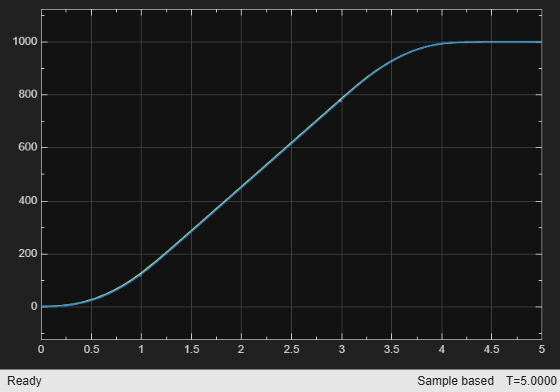

open_system([model '/Scope_Distance']);